# Deep Learning Simulink Model to Classify ECG Signals

## Prepare Data for Simulink Simulation

clear
addpath(fullfile("../data"))
addpath(fullfile("../models"))
addpath(fullfile("../helpers"))
load('ECG_Data_split.mat')
ecg_stream = timetable(testData','TimeStep',seconds(1/128));
classNames=["ARR","CHF","NSR"];

## Exercise 3.1

Navigate to the LSTM_Version subsystem and integrate the LSTM model in the block diagram. Specify the mask variables as indicated in the variant subsystem.

open('Ch3_Simulation.slx')
path = ['Ch3_Simulation','/Variant Subsystem/LSTM_Version/Resettable Subsystem/Stateful Classify/'];
set_param(path,'InputDataFormats',"{'sequenceinput', 'CT'}");


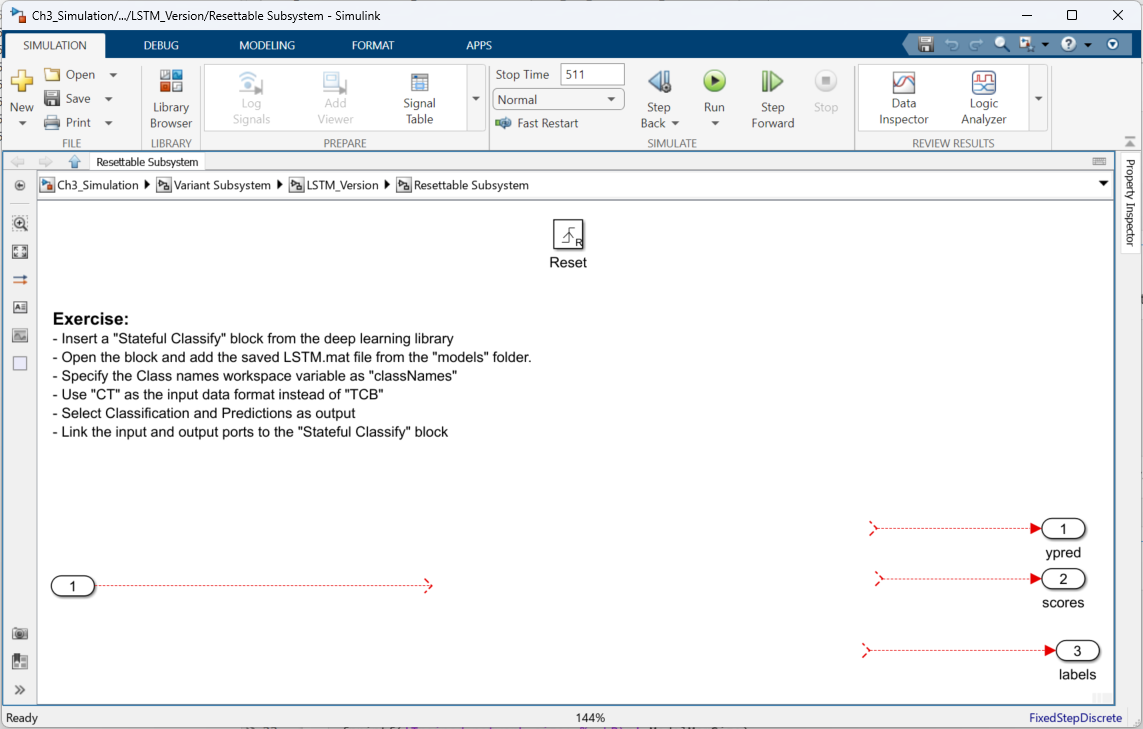

Check if the models (LSTM or also CNN) make accurate predictions by running different signals with the control switch in the top level block diagram. (signals 1-3 = ARR, 4-6 = CHF, 7-9 = NSR)

## Exercise 3.2

Profile the execution using the Simulink Profiler. Try to answer the following questions:

- How long does the execution of the LSTM or CNN block and the preprocessing take?

- How much memory does each model need? You might use code like the one below for this.

% add your code here

% wait for further instructions

## Compression of Neuronal Network

Evaluate if the network can be compressed.

load("LSTM.mat") %make sure the the LSTM net is loaded into the workspace
deepNetworkDesigner(net)

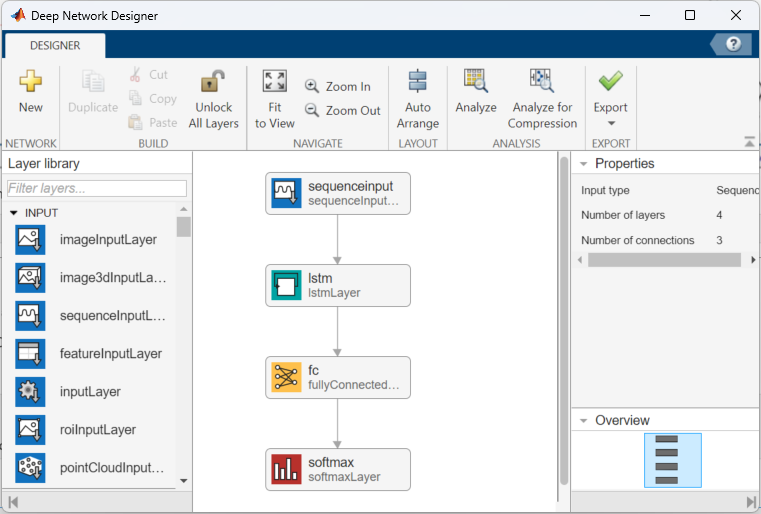

Click on "Analyze for Compression"

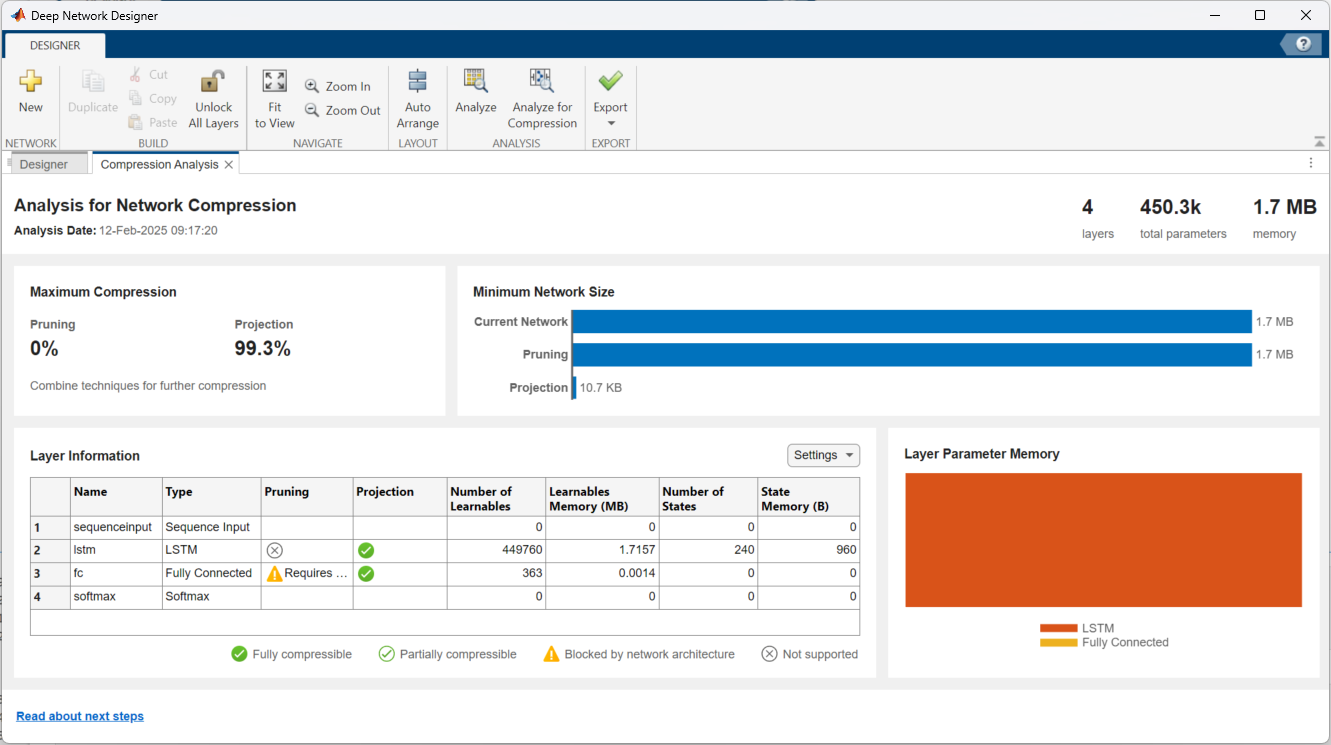

Hence, it might be a good choice to look into the compression by projection in more detail.

open("Ex3_Compression_LSTM.mlx")